## 1. Vaizdo įkėlimas

% Load the image
input_image = imread('new.jpg');

% Display the original image
%figure;
figure('Units', 'normalized', 'OuterPosition', [0 0 1 1]);

subplot(2, 3, 1);
imshow(input_image);
title('Original Image');

## 2. Triukšmo mažinimas

%% Noise Reduction with Gaussian Blur

% Convert to grayscale if it's a color image
gray_image = rgb2gray(input_image);

% Apply Gaussian Blur with different kernel sizes
blurred_5 = imgaussfilt(gray_image, 5);
blurred_9 = imgaussfilt(gray_image, 9);

% Display the blurred images
subplot(2, 3, 2);
imshow(blurred_5);
title('Gaussian Blur (5x5)');

subplot(2, 3, 3);
imshow(blurred_9);
title('Gaussian Blur (9x9)');


## 3. Kontrasto didinimas

%% Contrast Enhancement with Histogram Equalization

equalized_image = histeq(gray_image);

% Display the contrast-enhanced image
subplot(2, 3, 4);
imshow(equalized_image);
title('Histogram Equalization');

## 4. Vaizdo aštrumo didinimas

%% Image Sharpening using High-Pass Filter

% Define a sharpening kernel
sharpening_kernel = [-1 -1 -1; -1 9 -1; -1 -1 -1];

% Apply the sharpening filter
sharpened_image = imfilter(gray_image, sharpening_kernel);

% Display the sharpened image
subplot(2, 3, 5);
imshow(sharpened_image);
title('Image Sharpening');

## 5. Generatyvinių modelių taikymas

%% Model Application (Generative Models)
% In Lab02_Image_enhancement.ipynb file

## 6. Rezultatų vizualizacija

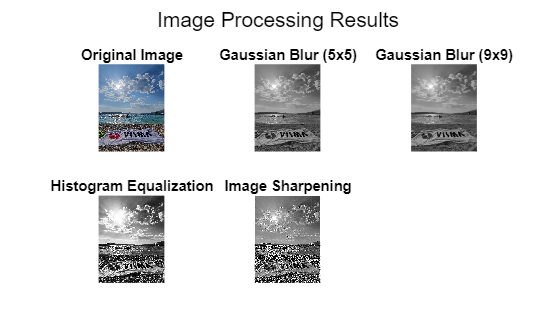

% Visualization
sgtitle('Image Processing Results');